%% params
root_path = 'E:\project\CACTI\experiment\simulation\dataset\simu_data\gray'

root_path = 'E:\project\CACTI\experiment\simulation\dataset\simu_data\gray'


Cr=20;
sel_frame = 24;
scale = 512;

% orig_name = 'YachtRide_%d.mat';
% orig_name = 'Jockey_%d.mat';
% orig_name = 'football_%d.mat';
% orig_name = 'ReadySteadyGo_%d.mat';
orig_name = 'hummingbird_%d.mat';

meas_idx = ceil(sel_frame/Cr)

meas_idx = 2

mask_name = ['multiplex_shift_binary_mask_' num2str(scale) '_' num2str(Cr) 'f.mat']

mask_name = 'multiplex_shift_binary_mask_512_20f.mat'


orig_full_name = sprintf(orig_name,scale)

orig_full_name = 'hummingbird_512.mat'


save_name = ['.\' orig_full_name(1:end-4) '_meas_Cr_' num2str(Cr) '.png']

save_name = '.\hummingbird_512_meas_Cr_20.png'

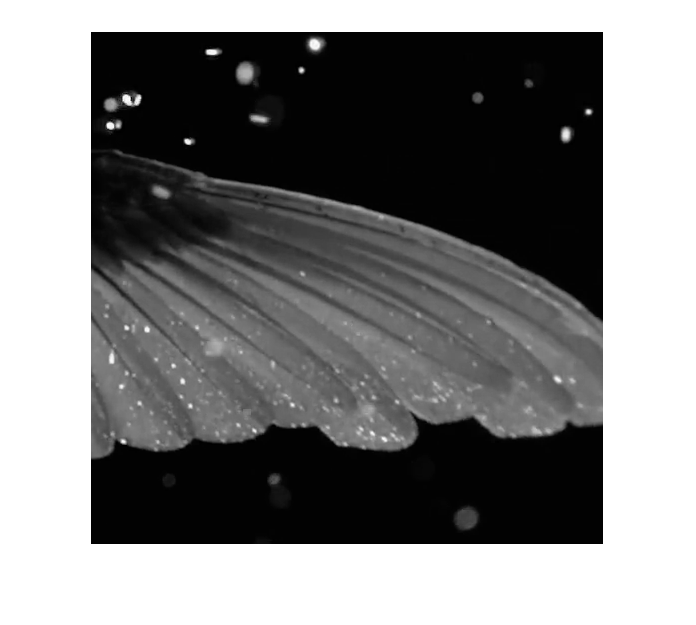


%% load data
mask = load([root_path '\mask\' mask_name]);
mask = mask.mask;
orig = load([root_path '\orig\' orig_full_name]);
orig = orig.orig;

imshow(orig(:,:,sel_frame))

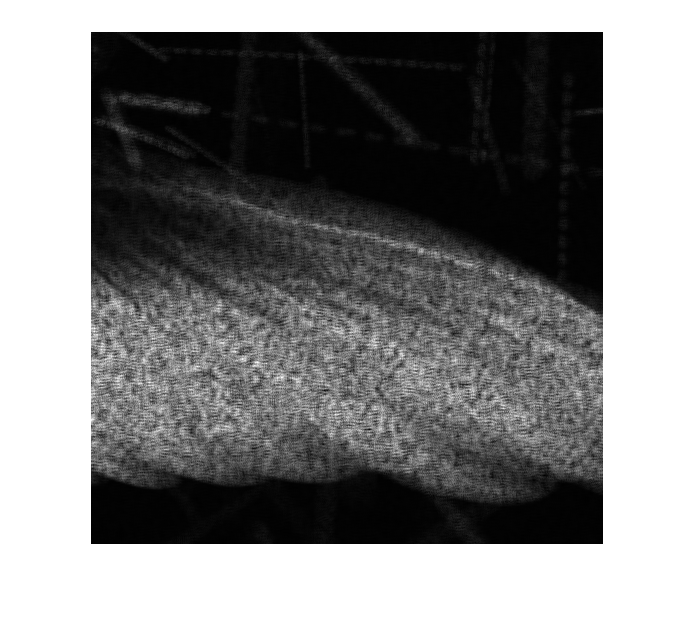



%%  calc meas
orig_sel=orig(:,:,1+(meas_idx-1)*Cr:meas_idx*Cr);
meas = sum(single(mask).*single(orig_sel),3);
norm_meas = uint8(meas./max(meas,[],'a')*255);
imwrite(norm_meas, save_name)
imshow(norm_meas,[])